# System Integration and Test Simulation

Configure a simulation that uses the following:

- Truth Locations - Field-collected ADSB data recorded with an RTL-SDR

- Detections and Sensor-based Tracks:

- Active radar (fusionRadarSensor)

- ADSB data (gpsSensor and ADSBReceiver)

- TrackFuser for C2 level tracks

- OSPA Metric, trackAssignmentMetrics, and errorMetrics for track accuracy analysis

close all force; clear; addpath('../HelperFunctions/')

## Configure Simulation

### Setup Scenario

Import truth location of aircraft and convert to trajectories for simulation

mapOrigin = [42.39423231362 -70.95934958874 0]; % Also defined in helperNed2ecefTrack, helperEcef2nedTrack, and fusionAlgorithm.m
load("TrackingScenarioTruth.mat")

Scenario Creation includes configuring the Active Radar Sensor

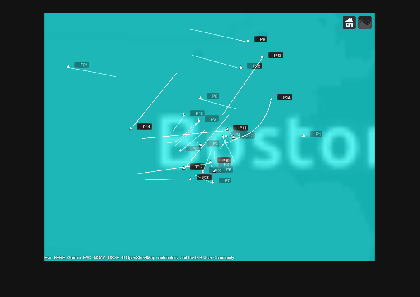

scenario = helperCreateScenario(tuningData, mapOrigin);
mapViewer = trackingGlobeViewer('ReferenceLocation',mapOrigin,'Basemap','streets-dark');
campos(mapViewer, mapOrigin + [0 -0.4 1e5]);
drawnow;
plotScenario(mapViewer,scenario);
snapshot(mapViewer);

### Secondary Sensor Configuration

Add ADSB for secondary target detection

Define Accuracy parameters for the gps sensor and assign ADSB transponder a

horAccuracy = 20;   % meters
vertAccuracy = 50;  % meters
velAccuracy = 0.4;  % m/s

gps = gpsSensor('PositionInputFormat','Geodetic',...
    'HorizontalPositionAccuracy',horAccuracy,...
    'VerticalPositionAccuracy',vertAccuracy,'VelocityAccuracy',velAccuracy);
numTargets = numel(scenario.Platforms)-2; % two platforms in scene are the sensor towers

Leverage a helper function to store GPS transponder in a structure.

transponderStruct = helperCreateTX(numTargets, gps);

### Configure ADSB Receiver for SSR

adsbRx = adsbReceiver('ReceiverIndex',2);

### Configure Tracker

[tracker,activeRadarSpec,targetSpec] = helperCreateTracker(scenario);

### Configure Track Fuser

You fuse radar tracks with ADS-B tracks obtained from the ADS-B receiver. To do this, you configure a central `trackFuser` object.

% Define the radar source configuration
radarConfig = fuserSourceConfiguration('SourceIndex',1,...
    'IsInitializingCentralTracks',false,...
    'CentralToLocalTransformFcn',@helperEcef2nedTrack,...
    'LocalToCentralTransformFcn',@helperNed2ecefTrack);

## **Step 1 - Adjust Coordinate Transform Configuration to Match Data**

**Directions:**

By running the script as configured, you should see that the adsbTracks are placed far from the truth positions of the targets. By adjusting the "CentralToLocalTransformFcn" and "LocalToCentralTransformFcn" to use the correct coordinate transforms, this should fix the issue.

Note - While I have given you the coordinate transforms, they are only flipped for the adsbConfig. In practice, you may have to generate this transforms yourself. It is powerful to use the visualization tools to check that you have done this setup correctly while configuring the functions.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% type "doc fuserSourceConfiguration" in the Command Window to find the documentation page for this function
% ADJUST THE adsbConfig's "CentralToLocalTransformFcn" and "LocalToCentralTransformFcn" to perform the
% transforms in the correct direction, ie opposite of the radarConfig:

% Define the adsb source configuration
adsbConfig = fuserSourceConfiguration('SourceIndex',2,...
    'IsInitializingCentralTracks',true,...
    'CentralToLocalTransformFcn',@helperNed2ecefTrack,...
    'LocalToCentralTransformFcn',@helperEcef2nedTrack); % This is solution - revert for the example

### Instantiate the track fuser 

Interpreted — used in Phase 1 only

fuser = trackFuser('FuserIndex',3,'MaxNumSources',2,...
    "AssignmentThreshold",[75 250],...
    "StateFusion",'Intersection',...
    'StateFusionParameters','trace',... 
    'ConfirmationThreshold',[2 3],... 
    'DeletionThreshold',[4 4],... 
    'SourceConfigurations',{radarConfig;adsbConfig});

## Phase 1 — Short Visual-Check Loop - Check User Config

Load Pre-recorded Sensor Data

load('SensorData.mat');

Reset Scenario, Tracker, Viewer, and Transponders

clear(mapViewer);
restart(scenario);
release(tracker);

Split dataset for easier parsing within simulation

trackerUpdateInterval = 1; % seconds
[activeRadarData] = helperSplitSensorData(sensorData, scenario.StopTime, trackerUpdateInterval);

### Run Short Simulation

Run a small number of steps with the User-defined fuser so user can see whether ADS-B tracks are landing on or far from the truth positions. If the adsbConfig is wrong, tracks will appear displaced on the globe.

**Check the figure and consider:**

- If ADS-B/fused tracks are displaced from truth, fix adsbConfig above and re-run

- If tracks overlay the truth, your config is correct — proceed to Phase 2

phase1Steps = 15;  % enough to see ADS-B and fused tracks appear
fprintf('\n--- Phase 1: Running %d steps with User-defined fuser for visual check ---\n', phase1Steps);


--- Phase 1: Running 15 steps with interpreted fuser for visual check ---


a1 = tic;

% Reset for Phase 1
clear(mapViewer);
restart(scenario);
release(tracker);
reset(adsbRx);
for i = 1:numTargets
    reset(transponderStruct(i).adsbTx);
end
plotPlatform(mapViewer,[scenario.Platforms{3:end}],TrajectoryMode="Full");

% Labels and colors
adsblabel = "       ADS-B";
radarlabel = "  Radar";
fusedlabel = string(sprintf('%s\n',"","Fused"));
adsbclr = [183 70 255]/255;
radarclr = [255 255 17]/255;
fusedclr = [255 105 41]/255;

wgs84 = wgs84Ellipsoid('meter');

for ind = 1:phase1Steps
    advance(scenario);

    % Coverage
    covcon = coverageConfig(scenario);
    plotCoverage(mapViewer,covcon,"ECEF",Color=[0 1 0])

    % Truth positions
    for i = 1:numel(scenario.Platforms)
        poseStruct = pose(scenario.Platforms{i},'CoordinateSystem','Geodetic');
        poseStruct.PlatformID = scenario.Platforms{i}.PlatformID;
        truePoseGPS(i) = poseStruct;
    end
    truePosePlot = platformPoses(scenario);
    plotPlatform(mapViewer, truePosePlot, 'ECEF');
    helperPlotActiveRadarData(mapViewer, activeRadarSpec, activeRadarData(ind));

    time = (ind - 1) * trackerUpdateInterval;

    % ADS-B processing
    adsbTracks     = objectTrack.empty;
    adsbTracksPlot = objectTrack.empty;
    radarTracks    = objectTrack.empty;
    fusedTracks    = objectTrack.empty;

    for i = 3:numel(truePoseGPS)
        position = truePoseGPS(i).Position;
        velocity = truePoseGPS(i).Velocity;
        if ~isnan(position)
            adsbMessages(i-2,1) = transponderStruct(i-2).adsbTx(position,velocity);
        end
    end
    adsbTracks = adsbRx(adsbMessages, time);
    adsbTracks = adsbTracks';
    clear adsbMessages
    adsbTracks = helperEnsureTimeAndParams(adsbTracks, time, helperEcefParams());

    % Convert to NED for globe viewer
    for i = 1:length(adsbTracks)
        adsbTracksPlot(i) = helperEcef2nedTrack(adsbTracks(i));
    end

    % Radar processing
    radarTracksStruct = trackingAlgorithm_mex({activeRadarData(ind)},targetSpec,activeRadarSpec);
    radarTracks = helperConvertToObjectTrack(radarTracksStruct);
    radarTracks = helperEnsureTimeAndParams(radarTracks, time, helperNedParams());

    % Fusion — INTERPRETED fuser using user's adsbConfig
    if isLocked(fuser) || ~isempty([adsbTracks;radarTracks])
        fusedTracks = fuser([adsbTracks;radarTracks], time);
    end

    % Convert fused tracks (ECEF) to NED for globe viewer plotting
    fusedTracksNED = objectTrack.empty;
    for i = 1:length(fusedTracks)
        fusedTracksNED(i) = helperEcef2nedTrack(fusedTracks(i));
    end

    % Force column orientation — interpreted fuser returns row vectors,
    % but helperPlotTracks vertcats with radarTracks (column).
    fusedTracksNED = fusedTracksNED(:);

    % Plot all tracks (fused tracks converted to NED to match viewer frame)
    mapViewer = helperPlotTracks(3,mapViewer,adsbTracksPlot,radarTracks,fusedTracksNED,...
        adsblabel,adsbclr,radarlabel,radarclr,fusedlabel,fusedclr);

    drawnow;
end

fprintf('Phase 1 complete (%.1f s).  Check the globe viewer.\n', toc(a1));

Phase 1 complete (44.0 s).  Check the globe viewer.


**Check the figure and consider:**

- If ADS-B/fused tracks are displaced from truth, fix adsbConfig above and re-run

- If tracks overlay the truth, your config is correct — proceed to Phase 2


snapshot(mapViewer);

## Phase 2 — Full Simulation with MEX Fuser - Show in Full Simulation

Phase 2 uses the MEX-compiled fusionAlgorithm (which has its own correct hardcoded config) for the full-duration simulation with metrics.

This is wrapped in helperRunFullSimulation() for a clean, single function call.

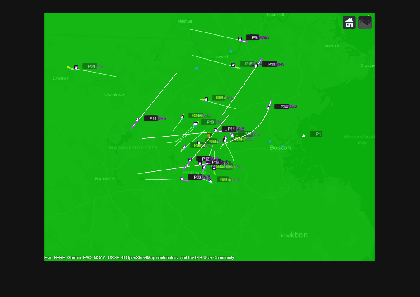

% Clean up the interpreted fuser from Phase 1
clear fuser  % <-- Phase 1 fuser is no longer needed

### Run Full Simulation

helperRunFullSimulation re-creates the scenario, tracker, and fuser from scratch using the MEX-compiled fusionAlgorithm_mex, runs the full simulation, and returns all logged data and metrics.

fprintf('--- Phase 2: Running full simulation with MEX fuser ---\n');
results = helperRunFullSimulation(tuningData, mapOrigin);
fprintf('Phase 2 complete (%.1f s wall-clock).\n\n', results.wallClockTime);

### Take Snapshot of Viewer (from Phase 2)

snapshot(results.mapViewer);

--- Phase 2: Running full simulation with MEX fuser ---


## Collect and Visualize Metrics

### Compute OSPA

ospa = trackOSPAMetric('CutoffDistance',500,'Distance','posabserr');

  Running 100 steps ...
  Sim loop done (58.5 s wall-clock).


Phase 2 complete (58.5 s wall-clock).



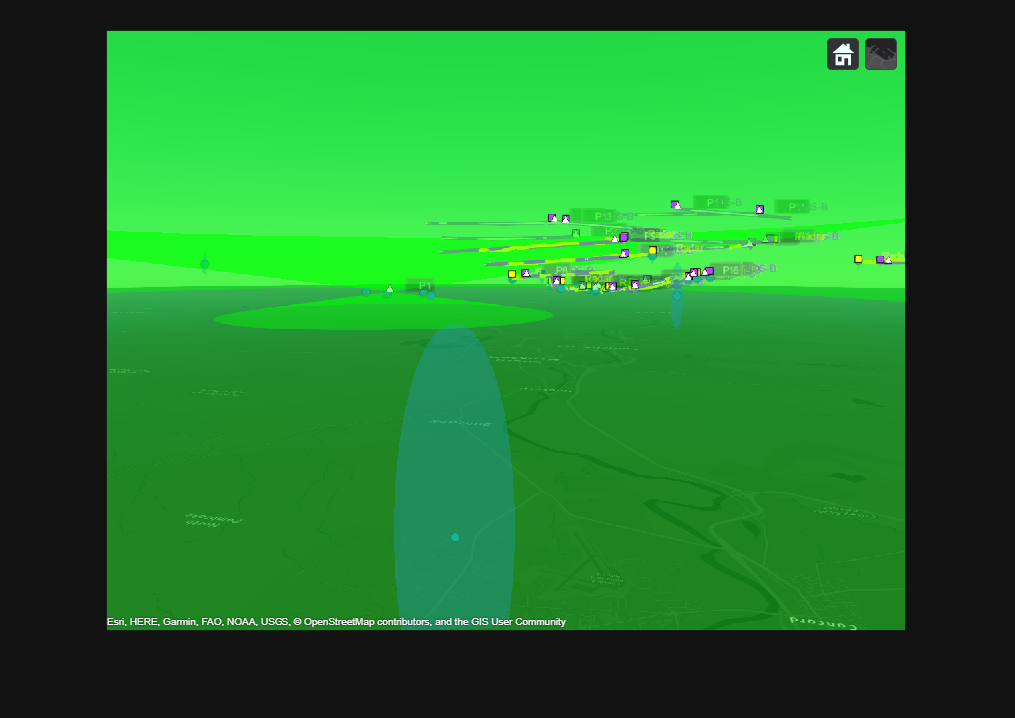

% Filter truths to moving targets only (drop first 2 platforms = sensor towers)
truthsFilteredNEDAll = cell(size(results.truePoseNEDAll));
for i = 1:numel(results.truePoseNEDAll)

    tp = results.truePoseNEDAll{i};
    if numel(tp) > 2
        tp = tp(3:end);
    else
        tp = tp([]);
    end
    truthsFilteredNEDAll{i} = tp;
end

% Radar OSPA
N_ospa = numel(results.radarTrackLog);
radarospa = nan(N_ospa,1); radarLoc = nan(N_ospa,1); radarCard = nan(N_ospa,1);
for i = 1:N_ospa
    tracks = results.radarTrackLog{i};
    truths = truthsFilteredNEDAll{i};
    if isempty(tracks) && isempty(truths), continue; end
    [radarospa(i), radarLoc(i), radarCard(i)] = ospa(tracks, truths);
end

% ADS-B OSPA
N_adsb = numel(results.adsbTrackLogNED);
adsbospa = nan(N_adsb,1); adsbLoc = nan(N_adsb,1); adsbCard = nan(N_adsb,1);
reset(ospa);
for i = 1:N_adsb
    tracks = results.adsbTrackLogNED{i};
    truths = truthsFilteredNEDAll{i};
    if isempty(tracks) && isempty(truths), continue; end
    [adsbospa(i), adsbLoc(i), adsbCard(i)] = ospa(tracks, truths);
end

% Fused OSPA
N_fused = numel(results.fusedTrackLog);
fusedospa = nan(N_fused,1); fuseLoc = nan(N_fused,1); fuseCard = nan(N_fused,1);
reset(ospa);
for i = 1:N_fused
    tracks = results.fusedTrackLog{i};
    truths = truthsFilteredNEDAll{i};
    if isempty(tracks) && isempty(truths), continue; end
    [fusedospa(i), fuseLoc(i), fuseCard(i)] = ospa(tracks, truths);
end

### Plot OSPA (Combined)

radarclr = [255 255 17]/255;
adsbclr  = [183 70 255]/255;
fusedclr = [255 105 41]/255;

figure
hold on
plot((0:(N_ospa-1))/60, radarospa, "Color",radarclr);
plot((0:(N_adsb-1))/60, adsbospa, "Color",adsbclr, 'LineWidth',2);
plot((0:(N_fused-1))/60, fusedospa, "Color",fusedclr);
l=legend('Primary (Radar)','Secondary (ADS-B)','Fused');
l.Color = [0.1 0.1 0.1];
l.TextColor = [1 1 1];
xlabel('Time (min)')
ylabel('OSPA')
ax = gca;
grid on; box on;
ax.Color = [0.1 0.1 0.1];
ax.GridColor = [1 1 1];

### Plot RMS Values

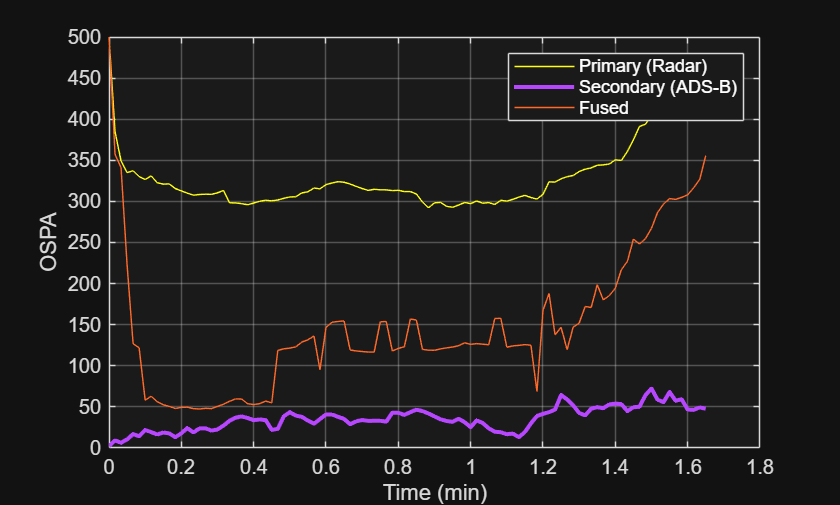

figure;
timeVec = 1:length(results.posRMSE);
subplot(2,2,1)
scatter(timeVec,results.posRMSE,'filled');
xlabel('Time step');
ylabel('RMS Error in Position (m)');
grid('on');

subplot(2,2,2)
scatter(timeVec,results.velRMSE,'filled');

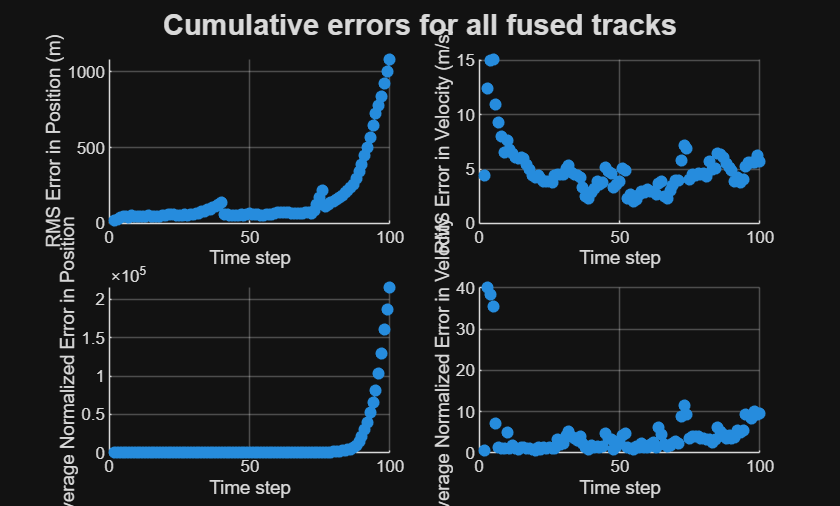

xlabel('Time step');
ylabel('RMS Error in Velocity (m/s)');
grid('on');

subplot(2,2,3)
scatter(timeVec,results.posANEES,'filled');
xlabel('Time step');
ylabel('Average Normalized Error in Position');
grid('on');

subplot(2,2,4)
scatter(timeVec,results.velANEES,'filled');
xlabel('Time step');
ylabel('Average Normalized Error in Velocity');
grid('on');

sgtitle('Cumulative errors for all fused tracks','FontWeight','bold');